# Optimal Seperating Hyperplanes

## Exercise A

% Clean up
close all;
clear;
clc;

% Load data
T = csvread('../Data/Synthetic2DNoOverlapp.csv');

X = T(:,1:2);
Y = T(:,3);

Change the 3 parameters to get an idea of how different kernel functions work

KernelFunction  = 'rbf';
KernelScale     = 0.1;
PolynomialOrder = 2;    

Then estimate the model and draw the decision boundary.

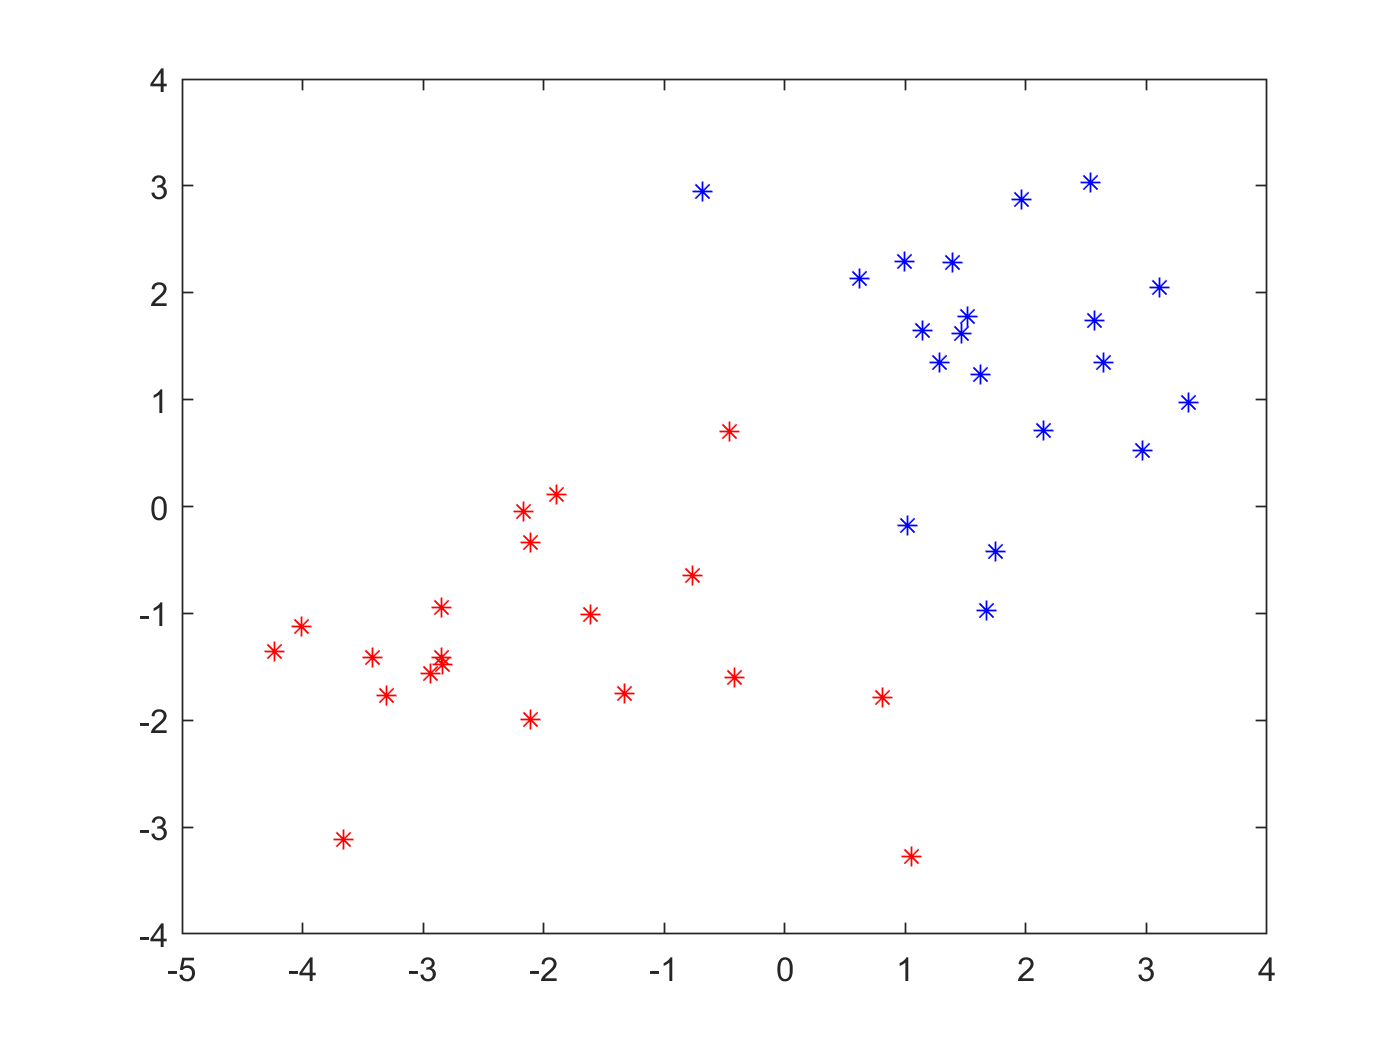

% Estimate model
switch KernelFunction
    case 'rbf'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%%
    case 'polynomial'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%%  
    case 'linear'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%% 
    otherwise
        disp('Unsupported kernel');
end

% Draw observations
figure()
plot(X(Y==1,1),X(Y==1,2),'b*')
hold on
plot(X(Y==0,1),X(Y==0,2),'r*')


%Draw the decision line
h = 0.1; 
[X1,X2] = meshgrid(-8:h:6,-5:h:5); %Create meshgrid
[~,score] = predict(svm,[X1(:),X2(:)]); % predict class label of gridpoints

Unrecognized function or variable 'svm'.

scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); % reshape the second column of score to the fit the grid 101*141
[~, h] = contour(X1,X2,scoreGrid,[0 0]); % Contour line the score matrix
set(h,'linecolor','k')
hold off

Reflect on the differences between "linear", "polynomial" and "rbf".

## Exercise B

clear;
close all; 
clc;

% load data
T = csvread('../Data/Synthetic2DOverlap.csv');

X = T(:,1:2);
Y = T(:,3);

Try different values for the kernel scale parameter

KernelScale = 0.2;

%%% Add you code here
%Fit svm. Name your model svm

%%%
          
% Draw observations
figure
plot(X(Y==1,1),X(Y==1,2),'b*')
hold on
plot(X(Y==0,1),X(Y==0,2),'r*')

%Draw the decision line
h = 0.1; 
[X1,X2] = meshgrid(-8:h:6,-5:h:5); %Create meshgrid
[~,score] = predict(svm,[X1(:),X2(:)]); % predict class label of gridpoints
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); % reshape the second column of score to the fit the grid 101*141
[~, h] = contour(X1,X2,scoreGrid,[0 0]); % Contour line the score matrix
set(h,'linecolor','k')
hold off

What do you think about the generalization ability of your solution?  